%% 2번 문제
clear; clc;

rng('default'); 

% (a)
mu = 100;
sigma = 4;
weights = mu + sigma * randn(10000, 20);

% (b) 
box_means = mean(weights, 2);

% (c)
failed_condition = (box_means < 98) | (box_means > 102);

% (d) 
failure_rate = mean(failed_condition);
fprintf('=== 2번 결과 ===\n');

=== 2번 결과 ===


fprintf('추정된 품질검사 불합격률: %.2f%%\n', failure_rate * 100);

추정된 품질검사 불합격률: 2.72%


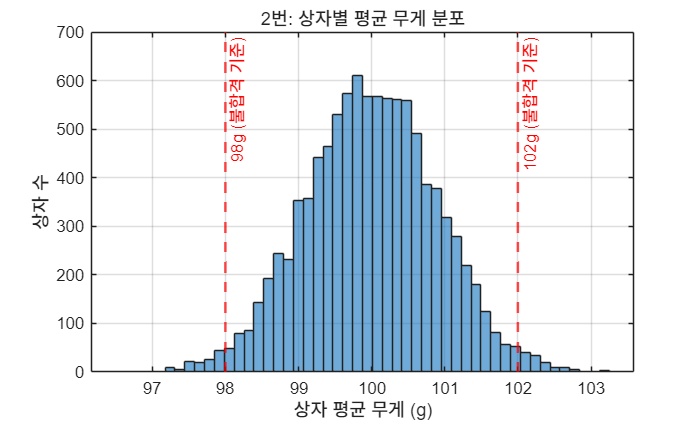


% (e) 
figure(2);
histogram(box_means, 50);
hold on;
xline(98, 'r--', '98g (불합격 기준)', 'LineWidth', 1.5);
xline(102, 'r--', '102g (불합격 기준)', 'LineWidth', 1.5);
hold off;
title('2번: 상자별 평균 무게 분포');
xlabel('상자 평균 무게 (g)');
ylabel('상자 수');
grid on;